# Voxelisation of atom probe data

Genereal description about voxelisation

To run this script, a decomposed pos file called posdec is needed. (See Workflow_FirstSteps)

## Create BinVectors from Distance

With the function binVectorsFromDistance you can create a set of grid vectors that can be used in nD binning. The bounds are calculated such that they don't go beyond the size of the dataset.

dist = [pos.x pos.y pos.z]; % x, y, z, coordinates from your decomposed pos file
bin = [1,1,1]; % bin width of each voxel in x y z, non isometric bins are possible.
mode = 'distance';
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode)

binCenters = 1×3 cell array
    {1×70 double}    {1×69 double}    {1×77 double}


binEdges = 1×3 cell array
    {1×71 double}    {1×70 double}    {1×78 double}


binCenters is a 3D vector containing the center points of each direction 

## Calculate the voxelisation of all atoms

gridVec = binCenters;
vox = posToVoxel(posdec, gridVec);

## Calculate the voxelisation of a specific atom species

use the same grid vectors as for the calculation for vox

species = {'Co'};
voxSpecies = posToVoxel(posdec,gridVec,species);
 

## Calculate the concentration of the specific atom species

conc = voxSpecies./vox

conc = conc(:,:,1) =

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       

## Calculate an isosurface of your concentration 

grid = meshgrid(gridVec{1}, gridVec{2}, gridVec{3}); % create a grid
threshold = 0.65

threshold = 0.6500

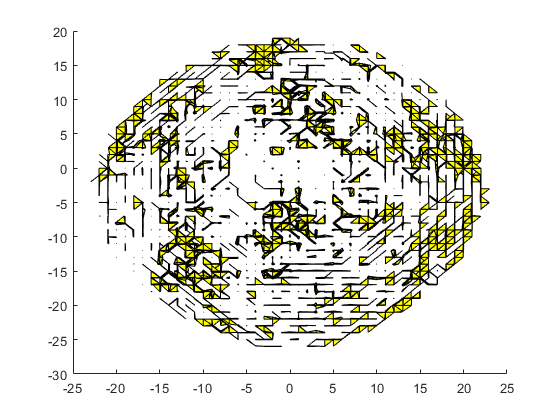

fv = isosurface(gridVec{2},gridVec{1},gridVec{3},conc,0.01); % calculate faces and vertices based on a thershold
patch(fv, 'FaceColor', [1 1 0]); 

axisSpatialAptify; 

'axisSpatialAptify' is not found in the current folder or on the MATLAB path, but exists in:
    Z:\GitHub-Matlab-Atomsonde\atom-probe-code
    Z:\GitHub-Matlab-Atomsonde\Atom-Probe-Toolbox

Change the MATLAB current folder or add its folder to the MATLAB path.

rotate3d on;

 

## posNdBin

voxNd = posNdBin(posdec, dist, binCenters)

Unable to perform assignment because the size of the left side is 1944445-by-1 and the size of the right side is 5537026-by-1.

Error in posNdBin (line 16)
    [~, loc(:,d)] = histc(distance(:,d),binEdges{d},1);